# HW6 -- Programming Constructs

1) The number of ways to choose $k$ objects from a set of $n$ objects is defined and calculated with the formula $\left(\begin{array}{c}n \\ k \end{array}\right) = \frac{n!}{k!(n-k)!}$. Define a Pascal matrix $P$ with the formula $P(i,j)=\left(\begin{array}{c}i+j-2 \\ i-1 \end{array}\right)$. Use this definition to find a Pascal matrix of dimensions *4x4*. Use Matlab's *pascal()* command to check your result.

myPasc = zeros(4, 4)

myPasc =        0              0              0              0       
       0              0              0              0       
       0              0              0              0       
       0              0              0              0       


for i = 1:4
    for j = 1:4
        myPasc(i,j)=factorial(i+j-2);
        myPasc(i,j)=myPasc(i,j)/factorial(i-1);
        myPasc(i,j)=myPasc(i,j)/factorial(j-1);
    end
end

pascal(4)==myPasc % result is all 1s, so it matches

ans = 4×4 logical array
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1


2) Write a for loop that will output the cubes of the first 10 positive integers. Use fprintf to output the results, which should include the integer and its cube. Write a second program that uses a while loop to produce an identical result. 

for n = 1:10
    fprintf('n = %d \t n^3 = %d \n', n, n^3)
end

n = 1 	 n^3 = 1 
n = 2 	 n^3 = 8 
n = 3 	 n^3 = 27 
n = 4 	 n^3 = 64 
n = 5 	 n^3 = 125 
n = 6 	 n^3 = 216 
n = 7 	 n^3 = 343 
n = 8 	 n^3 = 512 
n = 9 	 n^3 = 729 
n = 10 	 n^3 = 1000 



m = 1;
while m <= 10
    fprintf('m = %d \t m^3 = %d \n', m, m^3)
    m = m + 1;
end

m = 1 	 m^3 = 1 
m = 2 	 m^3 = 8 
m = 3 	 m^3 = 27 
m = 4 	 m^3 = 64 
m = 5 	 m^3 = 125 
m = 6 	 m^3 = 216 
m = 7 	 m^3 = 343 
m = 8 	 m^3 = 512 
m = 9 	 m^3 = 729 
m = 10 	 m^3 = 1000 


3) Write a single program that will count the number of divisors of each of the following integers: 20, 36, 84, and 96. (A positive integer k is a divisor of positive integer m if   m/k  is also an integer.)  Use fprintf to output each result in a form similar to "The number of divisors of 12 is 6. 

v = [20 36 84 96];
r = zeros(1, 4)

r =        0              0              0              0       

for i = 1:4
    for j = 1:v(i)
        r(i) = r(i) + ~rem(v(i), j);
    end
end
for i = 1:4
    fprintf("%d has %d divisors \n", v(i), r(i))
end

20 has 6 divisors 
36 has 9 divisors 
84 has 12 divisors 
96 has 12 divisors 


4) Write a program that uses nested for loops to produce Pythagorean Triples, positive integers a, b and c that satisfy $a^2+b^2 = c^2$. Find all such triples such that $1 \leq a, b, c \leq 20$ and use fprintf to produce nicely formatted results.

for i = 1:20
    for j = i:20 % prevents duplicate triples 
        for k = 1:20
            if i^2 + j^2 == k^2
                fprintf('%2d^2 + %2d^2 = %2d^2 \n',i,j,k)
            end
        end
    end
end

 3^2 +  4^2 =  5^2 
 5^2 + 12^2 = 13^2 
 6^2 +  8^2 = 10^2 
 8^2 + 15^2 = 17^2 
 9^2 + 12^2 = 15^2 
12^2 + 16^2 = 20^2 


5) We are interested in counting the number of points (x,y,z) in 3-space such that x,y,z are all non-negative integers and their sum is a given positive integer n. (These are sometimes called integer lattice points.) Write a program to do this when n=32.

latPointCount = 0;
n = 32;
for i = 0:n
    for j = 0:(n - i)
        for k = 0:(n - i - j)
            if i + j + k == n
                latPointCount = latPointCount + 1;
            end
        end
    end
end
latPointCount

latPointCount =      561       

6) Write a program to perform the following task: Use Matlab to draw a circle of radius 1 centered at the origin and inscribed in a square having vertices (1, 1), (-1, 1), (-1,-1), and (1,-1). The ratio of the area of the circle to the area of the square is pi : 4 or $\pi/4$. Hence, if we were to throw darts at the square in a random fashion, the ratio of darts inside the circle to the number of darts thrown should be approximately equal to $\pi/4$. Write a for loop that will plot 1000 randomly generated points inside the square. Use Matlab's rand command for this task. Each time a random point lands within the unit circle, increment a counter *hits*. When the *for* loop terminates, use *fprintf* to output the ratio darts that land inside the circle to the number of darts thrown. Calculate the relative error in approximating $\pi/4$ with this ratio.

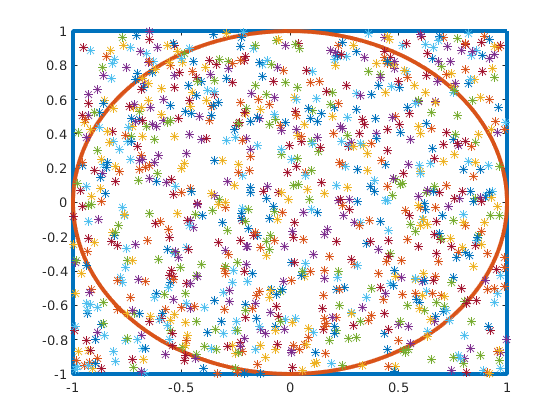

x = [1 -1 -1 1 1]; % x coords for square
y = [1 1 -1 -1 1]; % y coods for square
inCircle = 0;
plot(x,y,'-', "LineWidth", 3)
hold on
syms t
fplot(cos(t), sin(t), [0 2*pi], "LineWidth",3) % circle
for i = 1:1000
    rand1 = rand * 2 - 1;
    rand2 = rand * 2 - 1;
    if rand1^2 + rand2^2 <= 1 % tests if point is in unit circle
        inCircle = inCircle + 1;
    end
    plot(rand1,rand2, '*')
end

relErr = abs(pi/4 - inCircle/1000) / (pi / 4);
fprintf("Relative error: %.4f %%", relErr*100)

Relative error: 1.2225 %